## **Non-linear Model Trajectory with Custom Track**


$$\dot x(t)=u(t) \cos \theta(t) - v(t) \sin \theta(t)$$



$$\dot y(t)=u(t) \sin \theta(t) + v(t) \cos \theta(t)$$



$$u(t)=cte$$



$$\dot{v}(t) = -\frac{c_f + c_r}{M u} v(t) + \frac{c_r c - c_f b - M u^2}{M u} r(t) + \frac{c_f}{M} \delta(t)$$



$$\dot{r}(t) = \frac{c c_r - b c_f}{u I} v(t) - \frac{c^2 c_r + b^2 c_f}{u I} r(t) + \frac{c_f b}{I} \delta(t)$$


theta dot = r 

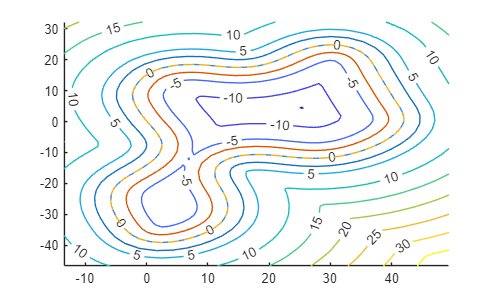

clc;clear;
%Define the track
track = load("circuitforalex.mat");
centerx = track.centers(:,1);
centery = track.centers(:,2);
innerx = track.Outx;
innery = track.Outy;
outx = track.Inx;
outy = track.Iny;
trackwidth = 4;
minx = min(outx); maxx= max(outx);
miny = min(outy); maxy= max(outy);

step_x = (maxx-minx)/60;
step_y = (maxy-miny)/50;
[gridx, gridy] = meshgrid((minx-5):step_x:(maxx+5), (miny-5):step_y:(maxy+5));

distance = zeros(size(gridx,1),size(gridx,2));

for i=1:size(gridx,1)
    for j=1:size(gridx,2)
        distance(i,j) = p_poly_dist(gridx(i,j),gridy(i,j),centerx,centery);
    end
end

figure
hold on
contour(gridx,gridy,distance,'ShowText','on')
plot(track.Inx,track.Iny,track.Outx,track.Outy,track.centers(:,1),track.centers(:,2),'--')


[DX, DY] = gradient(distance, step_x, step_y);
% index = zeros(size(distance,2),1);
% lowest = zeros(size(distance,2),1);
% 
% for i=1:size(distance,2)
%     lowest(i) = min(distance(:,i));
%     index(i) = find(distance(:,i) == lowest(i));
% end


% Define the parameters for the vehicle dynamics
c_f = 70000; % Front tire cornering stiffness
c_r = 50000; % Rear tire cornering stiffness
M = 1500;   % Mass of the vehicle in kg
I = 3000;   % Moment of inertia
b = 1.5;    % Distance from the center of gravity to the front axle
c = 1.5;    % Distance from the center of gravity to the rear axle

%initial and final conditions
ui= 5;
uf= 5;
thetai= atan2(centery(2)-centery(1), centerx(2)-centerx(1));
thetaf= atan2(centery(2)-centery(1), centerx(2)-centerx(1));
vi=0;
ri=0;
xi=centerx(1); xf=centerx(1);
yi=centery(1); yf=centery(1);

%Time step size
T = 0.2;

%Number of steps (initial guess)
N_min = 0;      % Theoretical minimum steps
N_max = 500;    % Theoretical maximum (Safe upper limit)
N = round((N_min + N_max) / 2); % Start in the middle

counter = 0;
max_iterations = 15;

%Optimization options
options = sdpsettings('solver', 'ipopt', 'verbose', 0);

track_len = length(centerx);
indices_guess = linspace(1, track_len, N); 
x_last = interp1(1:track_len, centerx, indices_guess, 'linear', 'extrap')';
y_last = interp1(1:track_len, centery, indices_guess, 'linear', 'extrap')';

%loop
while (N_max - N_min) > 1 && counter < max_iterations
    
    fprintf('Testing N = %d... ', N);
    
    %every time N changes, we regenerate a clean guess along the center
    guess_idx = linspace(1, length(centerx), N);
    x_last = interp1(1:length(centerx), centerx, guess_idx, 'linear', 'extrap')';
    y_last = interp1(1:length(centery), centery, guess_idx, 'linear', 'extrap')';
    
    yalmip('clear');
    
    %Unknowns
    x = sdpvar(N,1);
    y = sdpvar(N,1);
    theta = sdpvar(N,1);
    v = sdpvar(N,1);
    r = sdpvar(N,1);
    delta = sdpvar(N,1);
    u = sdpvar(N,1); %velocity as unknown
    
    %gradients
    d_val = interp2(gridx, gridy, distance, x_last, y_last, 'spline');
    dx_val = interp2(gridx, gridy, DX, x_last, y_last, 'spline');
    dy_val = interp2(gridx, gridy, DY, x_last, y_last, 'spline');
    d_val(isnan(d_val)) = 100; 
    dx_val(isnan(dx_val)) = 0; 
    dy_val(isnan(dy_val)) = 0;

    %Initial and final conditions
    F = [u(1) == ui,  ...
         x(1) == xi, ...
         y(1) == yi,  ...
         u(N) == uf, ...
         x(N) == xf, ...
         y(N) == yf, ...
         theta(1) == thetai, theta(N) == thetaf,...
         v(1) == vi,...
         r(1) == ri, ...
         abs(delta) <= deg2rad(40)];
    
    % Objective func
    obj = 0;  % sum of the squares of delta or V sum(dt) or (sum(ax.^2) + sum(delta.^2))
   
    %Problem conditions loop
    
    for k = 1:N-1
        F = [F x(k+1) == x(k) + T*(u(k)*cos(theta(k)) - v(k)*sin(theta(k)))];
        F = [F y(k+1) == y(k) + T*(u(k)*sin(theta(k)) + v(k)*cos(theta(k)))];
        F = [F v(k+1) == v(k) + T*(-(c_f + c_r)/(M*u(k)) * v(k) + (c_r*c - c_f*b - M*u(k)^2)/(M*u(k))...
            * r(k) + c_f/M * delta(k))];
        F = [F abs(v(k+1)) <= 2];
        F = [F r(k+1) == r(k) + T*((c*c_r - b*c_f)/(u(k)*I) * v(k) - (c^2*c_r + b^2*c_f)/(u(k)*I) * r(k)...
            + (c_f*b)/I * delta(k))];
        F = [F theta(k+1) == theta(k)+T*r(k)];
        F = [F u(k+1) <= 50];
        F = [F u(k+1) >= 2];
        %d = x(k)^2+y(k)^2; %car position
        %F = [F interp2(gridx,gridy,distance,x,y) <= trackwidth, interp2(gridx,gridy,distance,x,y) >= -trackwidth ]; 
        %TrackLimits - stay inside 
        % manual interp2 needed for yalmip: 
        % x = gridx * lambdax (weight) 
        % y = gridy * lambday 
        % d = lambdax transposed * distance matrix * lambday 
        % constraint on distance < 5 and > -5 (track width)
        % constraint on lambda x and lambda y 

        dist_predicted = d_val(k) + dx_val(k) * (x(k) - x_last(k)) + ...
                                dy_val(k) * (y(k) - y_last(k));
        F = [F dist_predicted <= trackwidth/2];
        F = [F dist_predicted >= -trackwidth/2];

        F = [F (x(k) - x_last(k)) >= -2];
        F = [F (x(k) - x_last(k)) <= 2];
        F = [F (y(k) - y_last(k)) >= -2];
        F = [F (y(k) - y_last(k)) <= 2];
        %obj = obj + delta(k)^2 + 0.1*(u(k) - 20)^2; % Encourage moving forward
    end

    optimization = optimize(F,obj,options);
    
    if optimization.problem == 0 %|| optimization.problem == 4 
        N_max = N;
        N = floor((N_min + N_max) / 2);
        fprintf('Feasible run\n')
        %saving the last solution to warm-start the new loops 
        sol_x = double(x);
        sol_y = double(y);
        sol_v = double(v);
        sol_theta = double(theta);
        sol_u = double(u);
        sol_delta = double(delta);
        sol_r = double(r);
        x_last = sol_x;
        y_last = sol_y;
        v_last = sol_v;
        theta_last = sol_theta;
        u_last = sol_u;
        delta_last = sol_delta;
        r_last = sol_r;
    else
        N_min = N;
        N = ceil((N_min + N_max) / 2);
        fprintf('Unfeasible run\n')
    end
    counter = counter + 1;
end

Testing N = 250... 

Unfeasible run


Testing N = 375... 

Unfeasible run


Testing N = 438... 

Unfeasible run


Testing N = 469... 

Unfeasible run


Testing N = 485... 

Cannot call restoration phase at point that is almost feasible for the restoration NLP (violation 4.899287e-011).
Abort in line search due to no other fall back.


Unfeasible run


Testing N = 493... 

Testing N = 247... 

Unfeasible run


Testing N = 249... 

Unfeasible run



N = N_max;
fprintf('Optimal N found: %d\n', N_max);

Optimal N found: 250


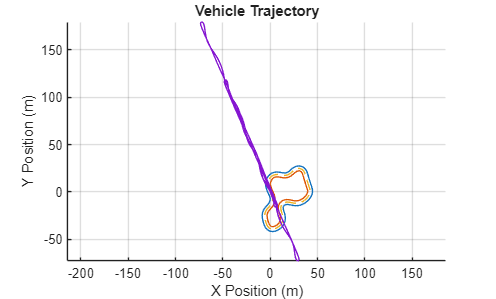

%Visualize Track
figure 
hold on
axis equal
grid on;
xlabel('X Position (m)');
ylabel('Y Position (m)'); 
title('Vehicle Trajectory');
plot(track.Inx,track.Iny,track.Outx,track.Outy,track.centers(:,1),track.centers(:,2),'--',x_last,y_last)

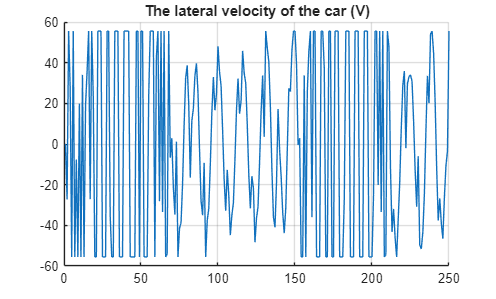


figure
hold on
%axis equal
grid on
title('The lateral velocity of the car (V)')
plot(v_last*100/3.6)

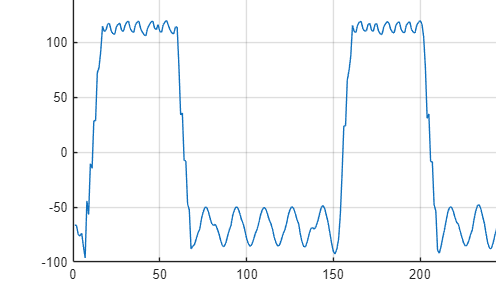


figure
hold on
%axis equal
grid on
title('angle of the car (theta)')
plot(rad2deg(theta_last))

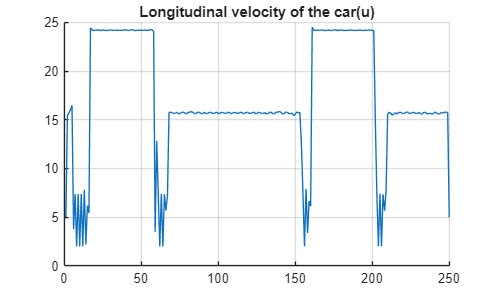


figure
hold on
%axis equal
grid on
title('Longitudinal velocity of the car(u)')
plot(u_last)

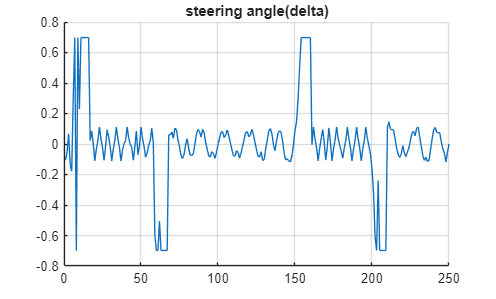


figure
hold on
grid on
title('steering angle(delta)')
plot(delta_last)